## Plot the workspace of the robot

step = 360/20;
nb_points = round(360/step);
%disp(nb_points);
%disp(nb_points^3);
xwork = zeros(nb_points^2) ; % reserving space for the variables, because
ywork = zeros(nb_points^2) ; % otherwise they would be created later within a loop.
zwork = zeros(nb_points^2);
i=1;
q5 = 0;
max = 0;

for q1 = 0:step:360
    for q2 = 0:step:180
        for q3 = -65:step:115
            for q4 = -180:step:0
                L_q = [q1 q2 q3 q4 q5];
                pos = forward_kinematics(L_q);
                if (pos(1)^2+pos(2)^2+pos(3)^2)^0.5 >0
                    max = (pos(1)^2+pos(2)^2+pos(3)^2)^0.5;
                    xwork(i) = pos(1);
                    ywork(i) = pos(2);
                    zwork(i) = pos(3);
                    i = i+1;
                end
            end
        end
    end
end    


figure (3)
set(3,'position')
plot3(0,0,0,'o')
hold on
[xp, yp] = meshgrid(-0.5:1:0.5); % Generate x and y data
zp = zeros(size(xp, 1)); % Generate z data
surf(xp, yp, zp) % Plot the surface
plot3(xwork,ywork,zwork,'rx')  % plot the  workspace of the robot
axis equal

title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
hold off


plot(xwork,ywork,'rx')
title('XY Workspace') ; xlabel('x (m)') ; ylabel('y (m)');
axis equal



plot(xwork,zwork,'rx')
title('XZ Workspace') ; xlabel('x (m)') ; ylabel('z (m)');
axis equal


plot(ywork,zwork,'rx')
title('YZ Workspace') ; xlabel('y (m)') ; ylabel('z (m)');
axis equal



## Inverse Kinematics

end_pose = [ 0.2  0.2  0.2  20 0]
theta_recalcule=inv_kin3(end_pose(1), end_pose(2) ,end_pose(3),end_pose(4),end_pose(5),1)
end_pose2 = forward_kinematics(theta_recalcule)
list2 = plot_links(theta_recalcule)
theta_recalcule=inv_kin3(end_pose(1), end_pose(2) ,end_pose(3),end_pose(4),end_pose(5),1)
end_pose2 = forward_kinematics(theta_recalcule)
list2 = plot_links(theta_recalcule)


%go to position

end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0]

         

hold on
set(gca,'XLim',[-0.1 0.3],'YLim',[-0.3 0.3],'ZLim',[0 0.4])
set(gcf,'Visible','on','Position', [10 10 900 600])
title('The five target positions') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
view(154,25)
grid on
for i = 1:length(end_pose)
    theta_recalcule=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    end_pose2 = forward_kinematics(theta_recalcule);
    list2 = plot_links(theta_recalcule);
    disp(theta_recalcule)
    drawnow
    
end


%FREE MOTION

end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000   45.0000   90.0000
    0.2000         0    0.3000   90.0000  180.0000
    0.2000    0.2000    0.2000   45.0000   90.0000
    0.2000    0.2000         0         0         0


nb_of_points = 50

nb_of_points = 50





all_theta = [];

for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    thetas_table = zeros(5,nb_of_points);
    
    for index_theta = 1:length(thetas_i1)
        spaced_thetas = linspace(thetas_i1(index_theta),thetas_i2(index_theta),nb_of_points) ;  % creates 500 points between 1 and 10 
        for index_point = 1:nb_of_points
            thetas_table(index_theta,index_point) = spaced_thetas(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        theta_now = [thetas_table(1,index_point), thetas_table(2,index_point), thetas_table(3,index_point), thetas_table(4,index_point), thetas_table(5,index_point)];
        [list_pos,drawing] = plot_links(theta_now);
        all_theta = [all_theta ;theta_now];
        drawnow
        pause(0.002)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now)

list_pos =          0         0    0.0810    0.0996    0.2000    0.2000
         0         0    0.0810    0.0996    0.2000    0.2000
         0    0.0790    0.1181   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0810 0.0996 0.2000 0.2000]
              YData: [0 0 0.0810 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.1181 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties


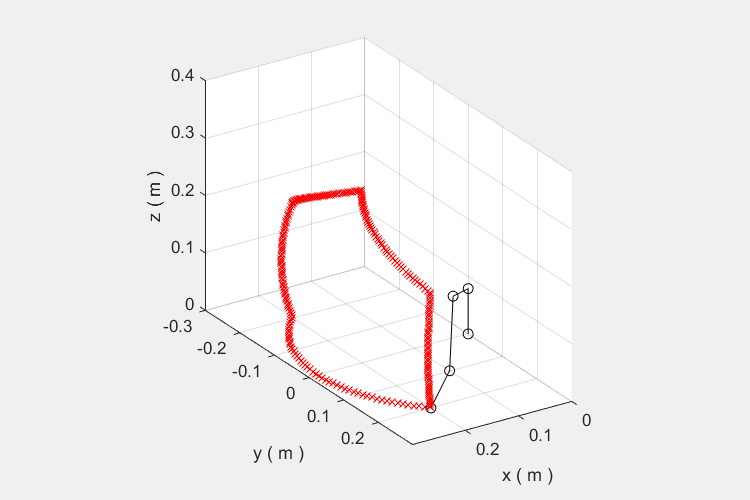

hold off 

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on
disp(all_theta(:,i_theta))

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    1.8367
    3.6735
    5.5102
    7.3469
    9.1837
   11.0204
   12.8571
   14.6939
   16.5306
   18.3673
   20.2041
   22.0408
   23.8776
   25.7143
   27.5510
   29.3878
   31.2245
   33.0612
   34.8980
   36.7347
   38.5714
   40.4082
   42.2449
   44.0816
   45.9184
   47.7551
   49.5918
   51.4286
   53.2653
   55.1020
   56.9388
   58.7755
   60.6122
   62.4490
   64.2857
   66.1224
   67.9592
   69.7959
   71.6327
   73.4694

disp(linspace(1,nb_of_points*5,nb_of_points*5))

  Columns 1 through 17

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17

  Columns 18 through 34

    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34

  Columns 35 through 51

    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51

  Columns 52 through 68

    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68

  Columns 69 through 85

    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85

  Columns 86 through 102

    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102

  Columns 103 through 119

   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119

  Columns 120 through 136

   120   121   122   123   124   125   126   127   128   129   130  

length(all_theta(:,i_theta))

ans = 250

length(linspace(1,nb_of_points*5,nb_of_points*5))

ans = 250

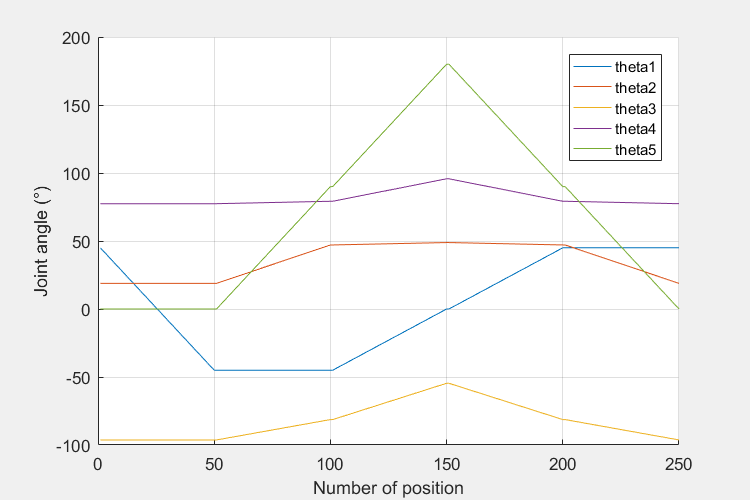

for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta))
end
legend('theta1','theta2','theta3','theta4','theta5')

%STRAIGHT LINE


end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000   45.0000   90.0000
    0.2000         0    0.3000   90.0000  180.0000
    0.2000    0.2000    0.2000   45.0000   90.0000
    0.2000    0.2000         0         0         0


nb_of_points = 50

nb_of_points = 50

all_theta = [];
for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    pos_table = zeros(5,nb_of_points);
    
 
    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        
        theta_now = inv_kin3(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point),1);
        all_theta = [all_theta ;theta_now];
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now)

list_pos =          0         0    0.0810    0.0996    0.2000    0.2000
         0         0    0.0810    0.0996    0.2000    0.2000
         0    0.0790    0.1181   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0810 0.0996 0.2000 0.2000]
              YData: [0 0 0.0810 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.1181 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties


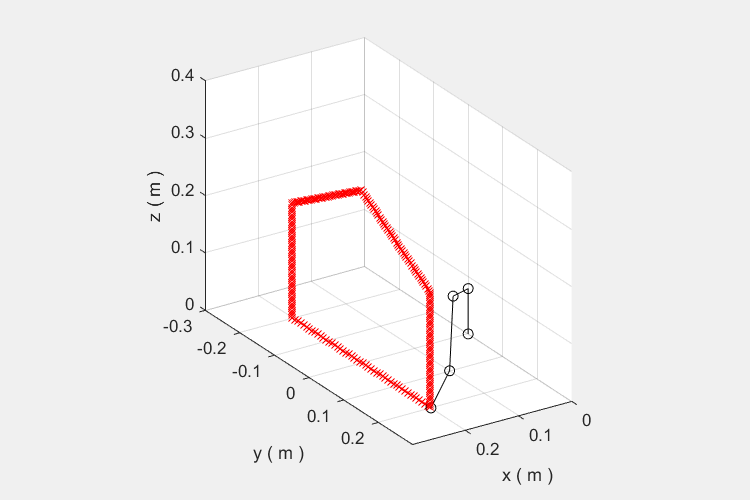


hold off 

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on
disp(all_theta(:,i_theta))

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    1.8367
    3.6735
    5.5102
    7.3469
    9.1837
   11.0204
   12.8571
   14.6939
   16.5306
   18.3673
   20.2041
   22.0408
   23.8776
   25.7143
   27.5510
   29.3878
   31.2245
   33.0612
   34.8980
   36.7347
   38.5714
   40.4082
   42.2449
   44.0816
   45.9184
   47.7551
   49.5918
   51.4286
   53.2653
   55.1020
   56.9388
   58.7755
   60.6122
   62.4490
   64.2857
   66.1224
   67.9592
   69.7959
   71.6327
   73.4694

disp(linspace(1,nb_of_points*5,nb_of_points*5))

  Columns 1 through 17

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17

  Columns 18 through 34

    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34

  Columns 35 through 51

    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51

  Columns 52 through 68

    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68

  Columns 69 through 85

    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85

  Columns 86 through 102

    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102

  Columns 103 through 119

   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119

  Columns 120 through 136

   120   121   122   123   124   125   126   127   128   129   130  

length(all_theta(:,i_theta))

ans = 250

length(linspace(1,nb_of_points*5,nb_of_points*5))

ans = 250

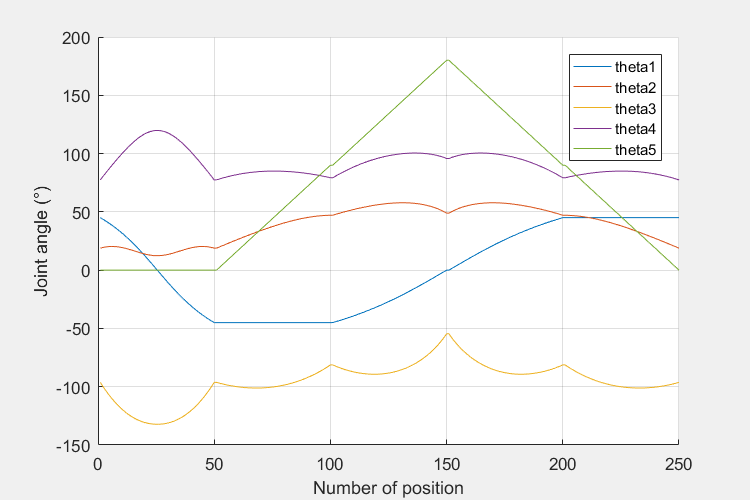

for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta))
end
legend('theta1','theta2','theta3','theta4','theta5')

%SWITH OBSTALCE

end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000   45.0000   90.0000
    0.2000         0    0.3000   90.0000  180.0000
    0.2000    0.2000    0.2000   45.0000   90.0000
    0.2000    0.2000         0         0         0


nb_of_points = 50

nb_of_points = 50


r_cyl = 0.05;

plot_obstacle(r_cyl);
all_theta = [];
for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    pos_table = zeros(5,nb_of_points);
    

    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
        disp(spaced_parameter)
    end
    
    for index_point = 1:nb_of_points
        dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        while dist_to_cylinder < 2*r_cyl
            pos_table(3,index_point) = pos_table(3,index_point) + 0.002 ; 
            pos_table(2,index_point) = pos_table(2,index_point) * 1.02 ;
            dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        end
        
        theta_now = inv_kin3(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point),1);
        all_theta = [all_theta;theta_now];
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

    0.2000    0.1918    0.1837    0.1755    0.1673    0.1592    0.1510    0.1429    0.1347    0.1265

  Columns 11 through 20

    0.1184    0.1102    0.1020    0.0939    0.0857    0.0776    0.0694    0.0612    0.0531    0.0449

  Columns 21 through 30

    0.0367    0.0286    0.0204    0.0122    0.0041   -0.0041   -0.0122   -0.0204   -0.02


[list_pos,drawing] = plot_links(theta_now)

list_pos =          0         0    0.0810    0.0996    0.2000    0.2000
         0         0    0.0810    0.0996    0.2000    0.2000
         0    0.0790    0.1181   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0810 0.0996 0.2000 0.2000]
              YData: [0 0 0.0810 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.1181 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties


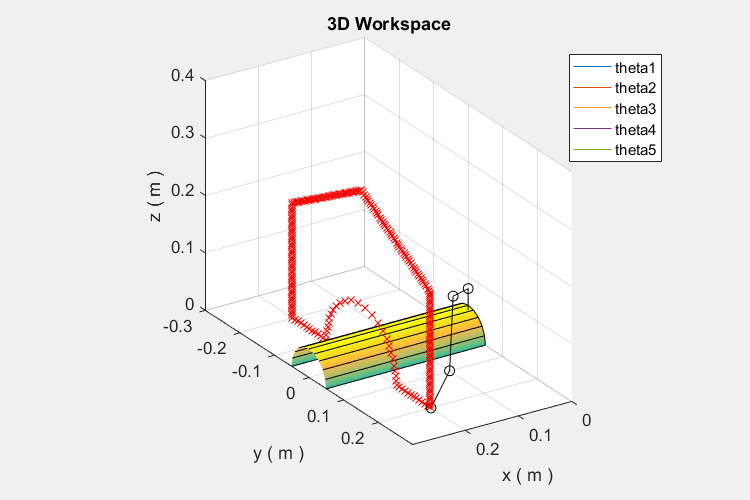


hold off 

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on
disp(all_theta(:,i_theta))

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    1.8367
    3.6735
    5.5102
    7.3469
    9.1837
   11.0204
   12.8571
   14.6939
   16.5306
   18.3673
   20.2041
   22.0408
   23.8776
   25.7143
   27.5510
   29.3878
   31.2245
   33.0612
   34.8980
   36.7347
   38.5714
   40.4082
   42.2449
   44.0816
   45.9184
   47.7551
   49.5918
   51.4286
   53.2653
   55.1020
   56.9388
   58.7755
   60.6122
   62.4490
   64.2857
   66.1224
   67.9592
   69.7959
   71.6327
   73.4694

disp(linspace(1,nb_of_points*5,nb_of_points*5))

  Columns 1 through 17

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17

  Columns 18 through 34

    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34

  Columns 35 through 51

    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51

  Columns 52 through 68

    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68

  Columns 69 through 85

    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85

  Columns 86 through 102

    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102

  Columns 103 through 119

   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119

  Columns 120 through 136

   120   121   122   123   124   125   126   127   128   129   130  

length(all_theta(:,i_theta))

ans = 250

length(linspace(1,nb_of_points*5,nb_of_points*5))

ans = 250

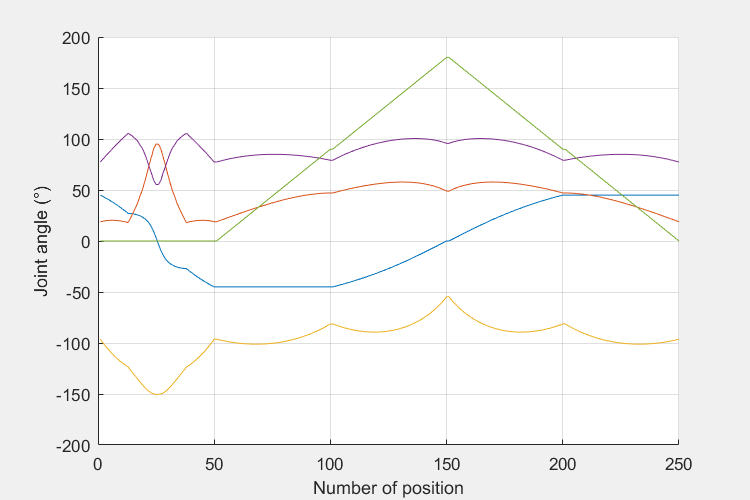

Undefined function 'xticklabels' for input arguments of type 'char'.


for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta))
end

legend('theta1','theta2','theta3','theta4','theta5')
